clear

addpath("functions\")

#### Add defect to pipe

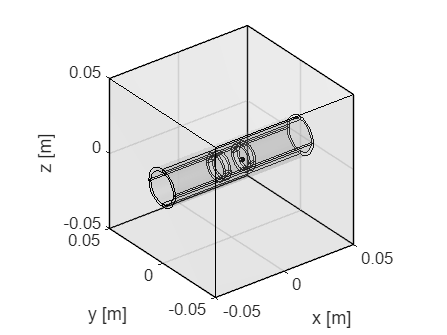

Model = myModel;
freqs = [1000 2000 4000 16000]; % (Hz)
shift = (-21:3:21) * 1e-3;
mesh_size = 3; % 1:finest 9:coarsest

Model = ComsolInterface('Build', Model);

ComsolInterface('AddCircularDefect', Model, deg2rad(30),  9e-3, 0.002, 10e-3, 11.0e-3)
ComsolInterface('AddCircularDefect', Model, deg2rad(30),  3e-3, 0.002, 10e-3, 11.5e-3)
ComsolInterface('AddCircularDefect', Model, deg2rad(30), -3e-3, 0.002, 10e-3, 12.0e-3)
ComsolInterface('AddCircularDefect', Model, deg2rad(30), -9e-3, 0.002, 10e-3, 12.5e-3)

figure
ComsolInterface('PlotGeometry', Model)

#### Compute fields

shift = reshape(shift, 1,[]);
freqs = reshape(freqs, 1,1,[]);

rho = Model.sensors.placement_rho;
phi = Model.sensors.placement_phi;
z   = zeros(size(rho));

delta_B = zeros(length(rho), length(shift), length(freqs));

for j = 1:length(shift)
for k = 1:length(freqs)
    tic
    ComsolInterface('Solve', Model, freqs(k), mesh_size, shift(j), true)
    Bphi1 = ComsolInterface('EvaluateField', Model, {'Bphi'}, rho,phi,z);

    ComsolInterface('Solve', Model, freqs(k), mesh_size, shift(j), false)
    Bphi2 = ComsolInterface('EvaluateField', Model, {'Bphi'}, rho,phi,z);
    fprintf("Solve %g mm shift %g Hz took %.2f seconds\n", shift(j)*1e3, freqs(k), toc)

    delta_B(:,j,k) = Bphi2 - Bphi1;
end
end

clear rho phi z j k Bphi1 Bphi2

#### Export sensor data

filename = sprintf('data/delta-B_%s.mat', datetime('now','Format','MMdd-HHmm'));
global defects
save(filename, 'delta_B', 'shift', 'freqs', 'defects')